Laboratorium 1

Przypomnienie podstaw środowiska Matlab oraz podstaw przetwarzania sygnałów.

Zad 1

Rozwiąż układ równań

x+2y+3z=1

4x+5,5y+6z=1

7x+8y+9,5z=1

syms x y z;

eqn1 = x + 2*y + 3*z == 1;
eqn2 = 4*x + 5.5*y + 6*z == 1;
eqn3 = 7*x + 8*y + 9.5*z == 1;

[A,B] = equationsToMatrix([eqn1, eqn2, eqn3], [x, y, z]);
X = linsolve(A, B);
X

$$X = \left(\begin{array}{c} -\frac{19}{29}\\ \frac{6}{29}\\ \frac{12}{29} \end{array}\right)$$

Zad 2

Sporządź wykres okręgu (równania parametryczne) dla t=[0;1)

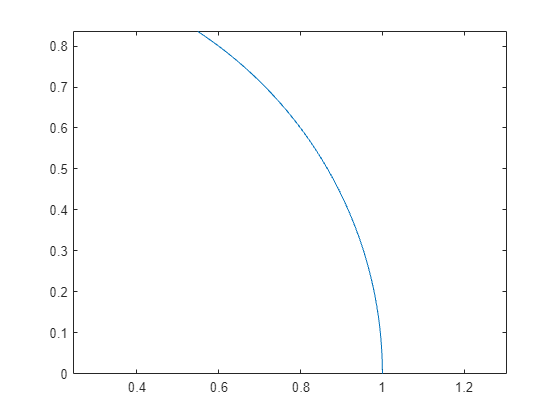

t = 0:0.01:1-0.01;
x = cos(t);
y = sin(t);


plot(x,y)
axis equal

Zad 3

Wygeneruj i przedstaw graficznie 3 okresy sygnałów. Amplituda A=+/- 1V, dla każdego wyznaczyć składową stałą i moc.

- Przebieg harmoniczny o częstotliwości f=1kHz

- Przebieg prostokątny o częstotliwości f=1kHz, wypełnieniu k=1/2 

- Przebieg piłokształtny o częstotliwości f=1kHz

- Przebieg trójkątny o częstotliwości f=1kHz

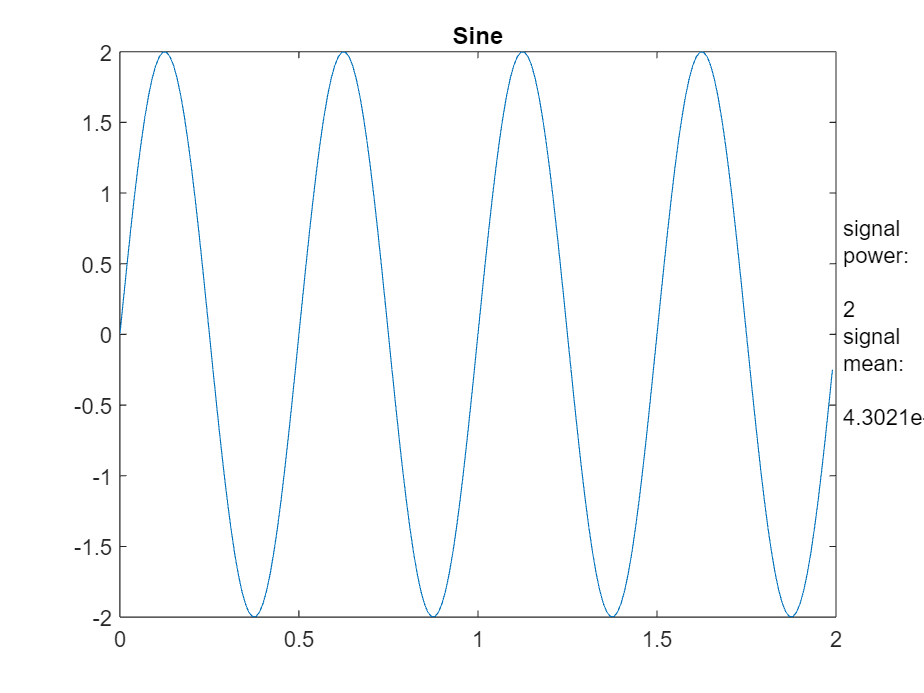

A = 2;
f =2;
k = 0.3;

w = 2*pi*f;
tmin = 0;
tmax = 2;
dt = 0.01;
t = tmin:dt:tmax-dt; %s

ad1 = A*sin(w*t);
power_ad1 = rms(ad1)^2;
mean_ad1 = mean(ad1);

plot(t, ad1);
title('Sine')
txt = ['signal power: ', string(power_ad1), 'signal mean: ', string(mean_ad1)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

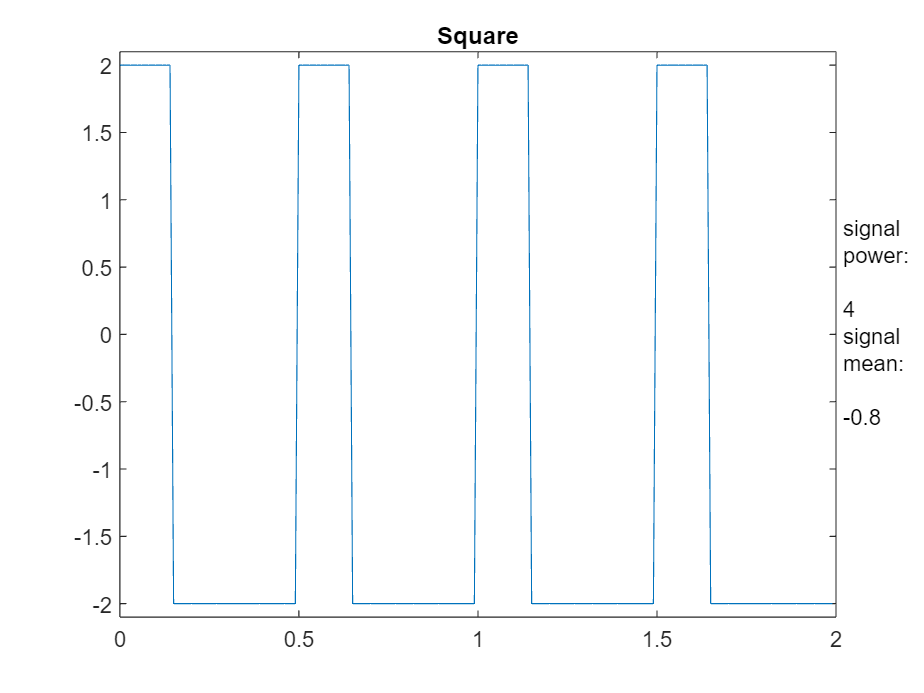

first_half = ones(1, round(1/(f*dt)*k)); second_half =  -1 * ones(1, round((1/(f*dt))*(1-k)));
ad2 = A * [first_half second_half];
for i = 0:(1/f)+1
    ad2 = cat(2,ad2,ad2);
end
power_ad2 = rms(ad2)^2;
mean_ad2 = mean(ad2);

plot(t, ad2)
ylim([-A-.1, A+0.1])
title('Square')
txt = ['signal power: ', string(power_ad2), 'signal mean: ', string(mean_ad2)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

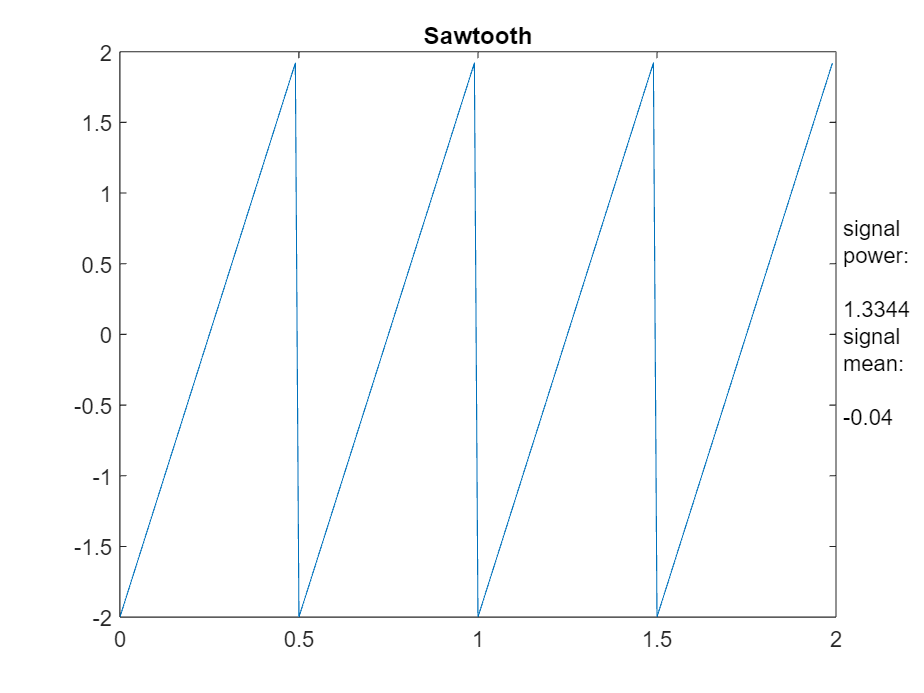

ad3 = A * sawtooth(w*t);
power_ad3 = rms(ad3)^2;
mean_ad3 = mean(ad3);

plot(t, ad3)
title('Sawtooth')
txt = ['signal power: ', string(power_ad3), 'signal mean: ', string(mean_ad3)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

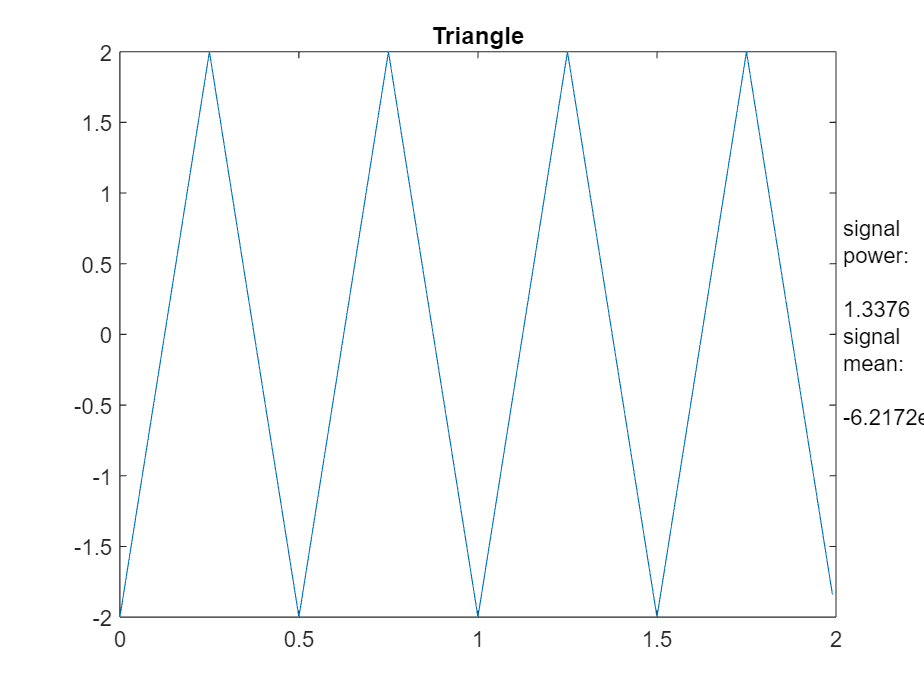


ad4 = A * sawtooth(w*t, .5);
power_ad4 = rms(ad4)^2;
mean_ad4 = mean(ad4);

plot(t, ad4)
title('Triangle')
txt = ['signal power: ', string(power_ad4), 'signal mean: ', string(mean_ad4)];
annotation('textbox', [.9, .7, 0, 0], 'string', txt)

***Zad 1***

***Zbudować przebieg „prostokątny” o częstotliwości f=30Hz za pomocą funkcji sinusoidalnych***

- Trzech

- Pięciu

- Dziesięciu

- Stu

- Analiza przypadku (1): sygnał cyfrowy ma częstotliwość 1 MHz (2 Mbit/s), jest reprezentowany odpowiednio przez 1 i 3 oraz 1 i 3 i 5 harmoniczną, szerokość pasma, reprezentacja sygnału.

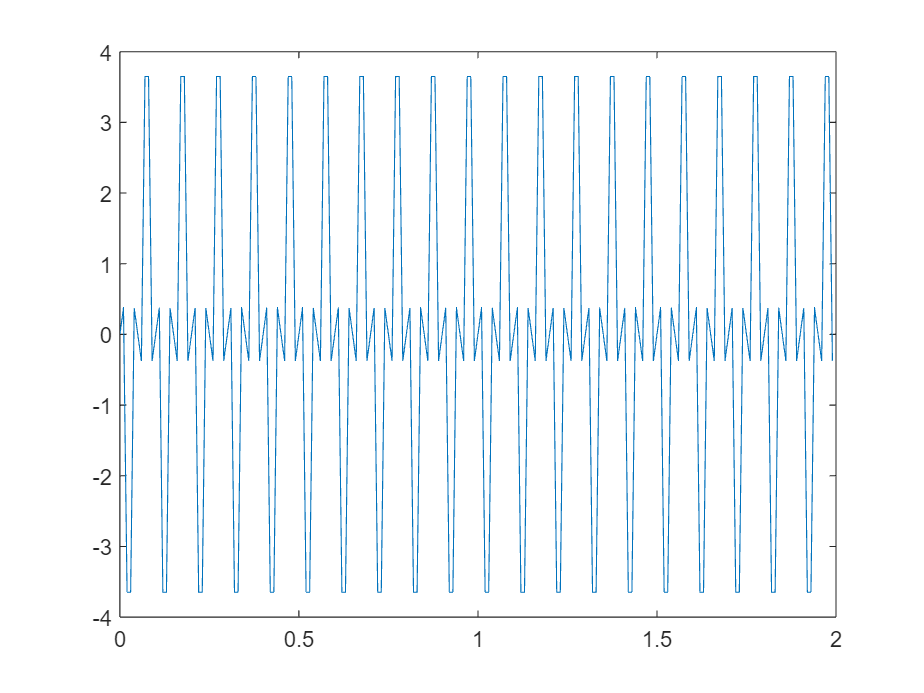

w1 = 2*pi*30;
w2 = 2*pi*90;
w3 = 2*pi*150;

sin1 = A * sin(w1*t);
sin3 = 0.3 * A * sin(w2*t);
sin7 = 0.7 * A * sin(w3*t);

combined_sines = sin1 + sin2 + sin3;

plot(t, combined_sines)